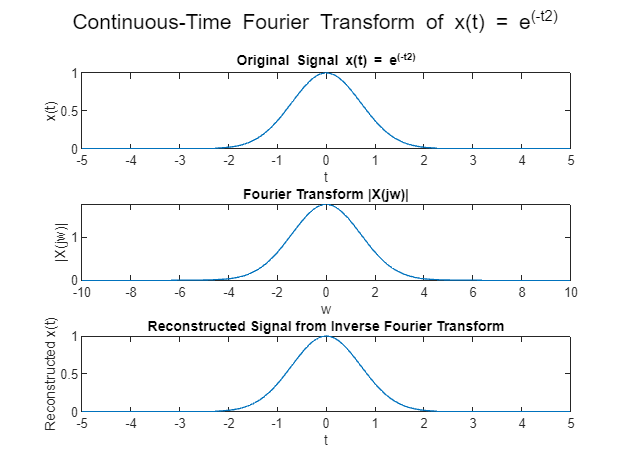

% Define symbolic variables
syms t w

% Define the signal x(t)
x_t = exp(-t^2);

% Calculate the Fourier transform of x(t)
X_w = CTFT(x_t);

% Calculate the Inverse Fourier Transform to get the original signal
x_reconstructed_t = ICTFT(X_w);

% Plot the original signal, its Fourier transform, and the reconstructed signal
figure;

% Original signal x(t)
subplot(3, 1, 1);
fplot(x_t, [-5, 5]);
title('Original Signal x(t) = e^(-t^2)');
xlabel('t');
ylabel('x(t)');

% Fourier transform X(jw)
subplot(3, 1, 2);
fplot(abs(X_w), [-10, 10]);
title('Fourier Transform |X(jw)|');
xlabel('w');
ylabel('|X(jw)|');

% Reconstructed signal from Inverse Fourier Transform
subplot(3, 1, 3);
fplot(x_reconstructed_t, [-5, 5]);
title('Reconstructed Signal from Inverse Fourier Transform');
xlabel('t');
ylabel('Reconstructed x(t)');

% Adjust subplot layout
sgtitle('Continuous-Time Fourier Transform of x(t) = e^(-t^2)');

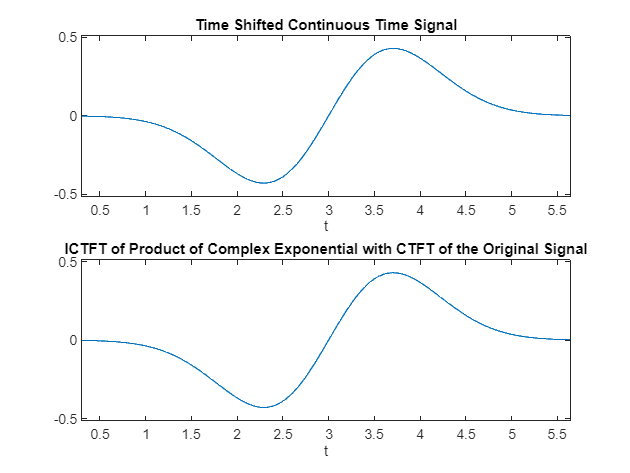

% Symbolic variables
syms w t

to = 3;
x = t * exp(-t^2);

figure;

% LHS
LHS = subs(x, t, t-to);
subplot(2,1,1);
ezplot(LHS);

title('Time Shifted Continuous Time Signal');

% RHS
X = CTFT(x);
Z = X .* exp(-1i .* w .* to);

RHS = ICTFT(Z);
subplot(2,1,2);
ezplot(RHS);

title('ICTFT of Product of Complex Exponential with CTFT of the Original Signal')

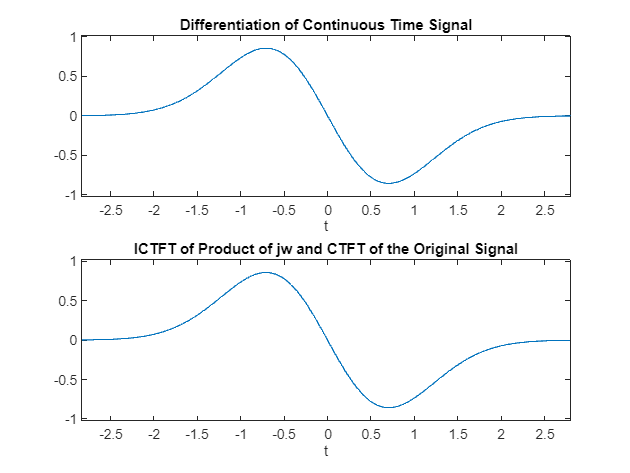

syms w t
y = exp(-t^2);

figure;

% LHS
LHS = diff(y,t);

subplot(2,1,1);
ezplot(LHS);

title('Differentiation of Continuous Time Signal');

% RHS
Y = CTFT(y);
Z = (1i .* w) * (Y);

RHS = ICTFT(Z);

subplot(2,1,2);
ezplot(RHS);

title('ICTFT of Product of jw and CTFT of the Original Signal');